clear
% simultion of 4 metagriding

## constants


eta = 377; %ohm
f= 10*10^9; %Hz
c = 3*10^8; %m/s
lambda = c/f;
k = 2*pi/lambda;
omega = 2*pi*f;
w = 3*0.0254e-3; % meters, 3 mil
reff = w/4;


## paramters


theta_in = 10*pi/180; %rads
theta_out = 70*pi/180;% rads
phi = 25*pi/180; % rads
Ein = 1;

sinin = sin(theta_in);
cosin = cos(theta_in);
sinout = sin(theta_out);
cosout = cos(theta_out);

Zin = eta/cos(theta_in);
Zout = eta/cos(theta_out);
Lambda = lambda/abs(sinout-sinin);


## vars


I = sym('I', [4 1]);
d = sym('d', [1,4]);
h = sym('h', [1,4]);
syms sin_in sin_out cos_in cos_out Z_in Z_out phase Lam K;
% phase = exp(1j*phi)
% Lam = Lambda*E_in 


## equations  - current as a function of everything


eq1 = exp(1j*K*(sin_in*d+cos_in*h))*I == 2*Lam/Z_in;
eq2 = exp(1j*K*(sin_out*d+cos_out*h))*I == 0;
eq3 = exp(1j*K*(sin_in*d-cos_in*h))*I == 0;
eq4 = exp(1j*K*(sin_out*d-cos_out*h))*I == 2*Lam*phase/Z_out;
eqns = [eq1,eq2,eq3,eq4];
Currents = solve(eqns,I);
Is1 = subs(Currents.I1,[sin_in sin_out cos_in cos_out Z_in Z_out phase Lam K],[sinin sinout cosin cosout Zin Zout exp(1j*phi) Lambda*Ein k]);
Is2 = subs(Currents.I2,[sin_in sin_out cos_in cos_out Z_in Z_out phase Lam K],[sinin sinout cosin cosout Zin Zout exp(1j*phi) Lambda*Ein k]);
Is3 = subs(Currents.I3,[sin_in sin_out cos_in cos_out Z_in Z_out phase Lam K],[sinin sinout cosin cosout Zin Zout exp(1j*phi) Lambda*Ein k]);
Is4 = subs(Currents.I4,[sin_in sin_out cos_in cos_out Z_in Z_out phase Lam K],[sinin sinout cosin cosout Zin Zout exp(1j*phi) Lambda*Ein k]);
Is=[Is1,Is2,Is3,Is4];


## Optimization parameters

x0=[0.0028,0.0330,0.0143,0.0113,0.0139,0.0263];
N=1000;
save('var.mat');

## Optimization

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    8.510866e-02    0.000e+00    1.525e+02
    1      21    3.382263e+00    1.044e-03    6.485e+02    2.746e-02


    2      29    2.775010e+00    3.648e-02    1.657e+03    6.220e-02


    3      37    1.958979e+00    5.687e-02    1.815e+03    2.787e-02


    4      44    6.594074e+00    5.337e-02    3.824e+03    1.918e-01


    5      51    5.620222e+00    5.387e-02    2.441e+03    1.016e-03


    6      58    5.134040e+00    5.114e-02    2.387e+03    9.645e-02


    7      65    1.245573e+01    3.787e-02    1.942e+04    8.349e-02


    8      73    1.213980e+01    3.802e-02    1.181e+04    2.047e-04


    9      81    6.405948e+00    3.484e-02    7.471e+03    3.736e-03


   10      88    5.257523e+00    3.479e-02    1.485e+03    2.398e-03


   11      95    7.483038e+00    3.411e-02    1.717e+04    7.209e-03


   12     102    4.080775e+00    3.122e-02    2.844e+04    3.889e-02


   13     110    3.641641e+00    3.131e-02    3.883e+03    9.778e-05


   14     117    3.684575e+00    3.116e-02    3.814e+03    1.302e-03


   15     125    4.424511e+00    2.638e-02    1.021e+04    3.125e-02


   16     132    7.668870e+00    1.840e-02    4.438e+03    4.143e-02


   17     140    7.561216e+00    1.849e-02    4.042e+03    9.802e-05


   18     147    7.529176e+00    1.830e-02    4.303e+03    3.150e-04


   19     154    6.083454e+00    1.885e-02    6.936e+03    4.606e-03


   20     162    6.082952e+00    1.885e-02    6.916e+03    2.030e-05


   21     169    1.878568e+01    1.576e-02    2.584e+04    6.132e-03


   22     176    1.922548e+01    1.565e-02    3.722e+04    1.941e-04


   23     183    1.910906e+01    1.564e-02    3.679e+04    3.964e-05


   24     190    8.249066e+00    9.837e-03    1.404e+04    1.296e-02


   25     197    7.332729e+00    9.868e-03    9.896e+03    8.458e-05


   26     206    7.306650e+00    9.867e-03    9.797e+03    1.147e-05


   27     214    7.244552e+00    9.866e-03    9.560e+03    2.048e-05


   28     221    6.645374e+00    9.851e-03    7.524e+03    1.281e-04


   29     228    4.052631e+00    9.691e-03    3.428e+03    1.174e-03


   30     235    4.486791e+00    1.400e-03    3.973e+03    6.463e-02


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
   31     242    5.107135e+00    1.345e-03    6.419e+03    3.375e-04


   32     249    7.121046e+00    0.000e+00    3.148e+05    5.627e-03


   33     257    6.134946e+00    0.000e+00    4.205e+04    1.035e-04


   34     264    5.823503e+00    0.000e+00    4.791e+04    5.556e-04


   35     271    5.252523e+00    0.000e+00    4.316e+04    1.180e-03


   36     278    4.802523e+00    0.000e+00    3.320e+04    4.221e-04


   37     286    3.639368e+00    0.000e+00    1.463e+04    1.863e-03


   38     294    3.251548e+00    0.000e+00    8.482e+03    1.008e-03


   39     301    2.330998e+00    0.000e+00    2.405e+04    1.969e-03


   40     308    1.945155e+00    0.000e+00    1.512e+04    1.091e-03


   41     316    1.667506e+00    0.000e+00    1.157e+04    8.535e-05


   42     324    1.236623e+00    0.000e+00    1.350e+03    6.819e-04


   43     331    1.237115e+00    0.000e+00    1.614e+03    1.251e-04


   44     338    1.365927e+00    0.000e+00    1.764e+03    8.522e-04


   45     345    1.290381e+00    0.000e+00    1.523e+03    3.665e-04


   46     352    1.237432e+00    0.000e+00    1.363e+03    2.161e-04


   47     359    1.181856e+00    0.000e+00    2.743e+03    2.076e-04


   48     371    9.782544e-01    0.000e+00    9.996e+03    2.199e-04


   49     381    9.543002e-01    0.000e+00    3.234e+04    3.152e-05


   50     388    9.290950e-01    0.000e+00    8.334e+03    4.540e-05


   51     395    9.085551e-01    0.000e+00    2.377e+04    2.191e-04


   52     404    8.819481e-01    0.000e+00    4.529e+04    5.380e-05


   53     411    8.917705e-01    0.000e+00    3.044e+04    1.261e-04


   54     423    8.902116e-01    0.000e+00    2.999e+04    9.876e-08


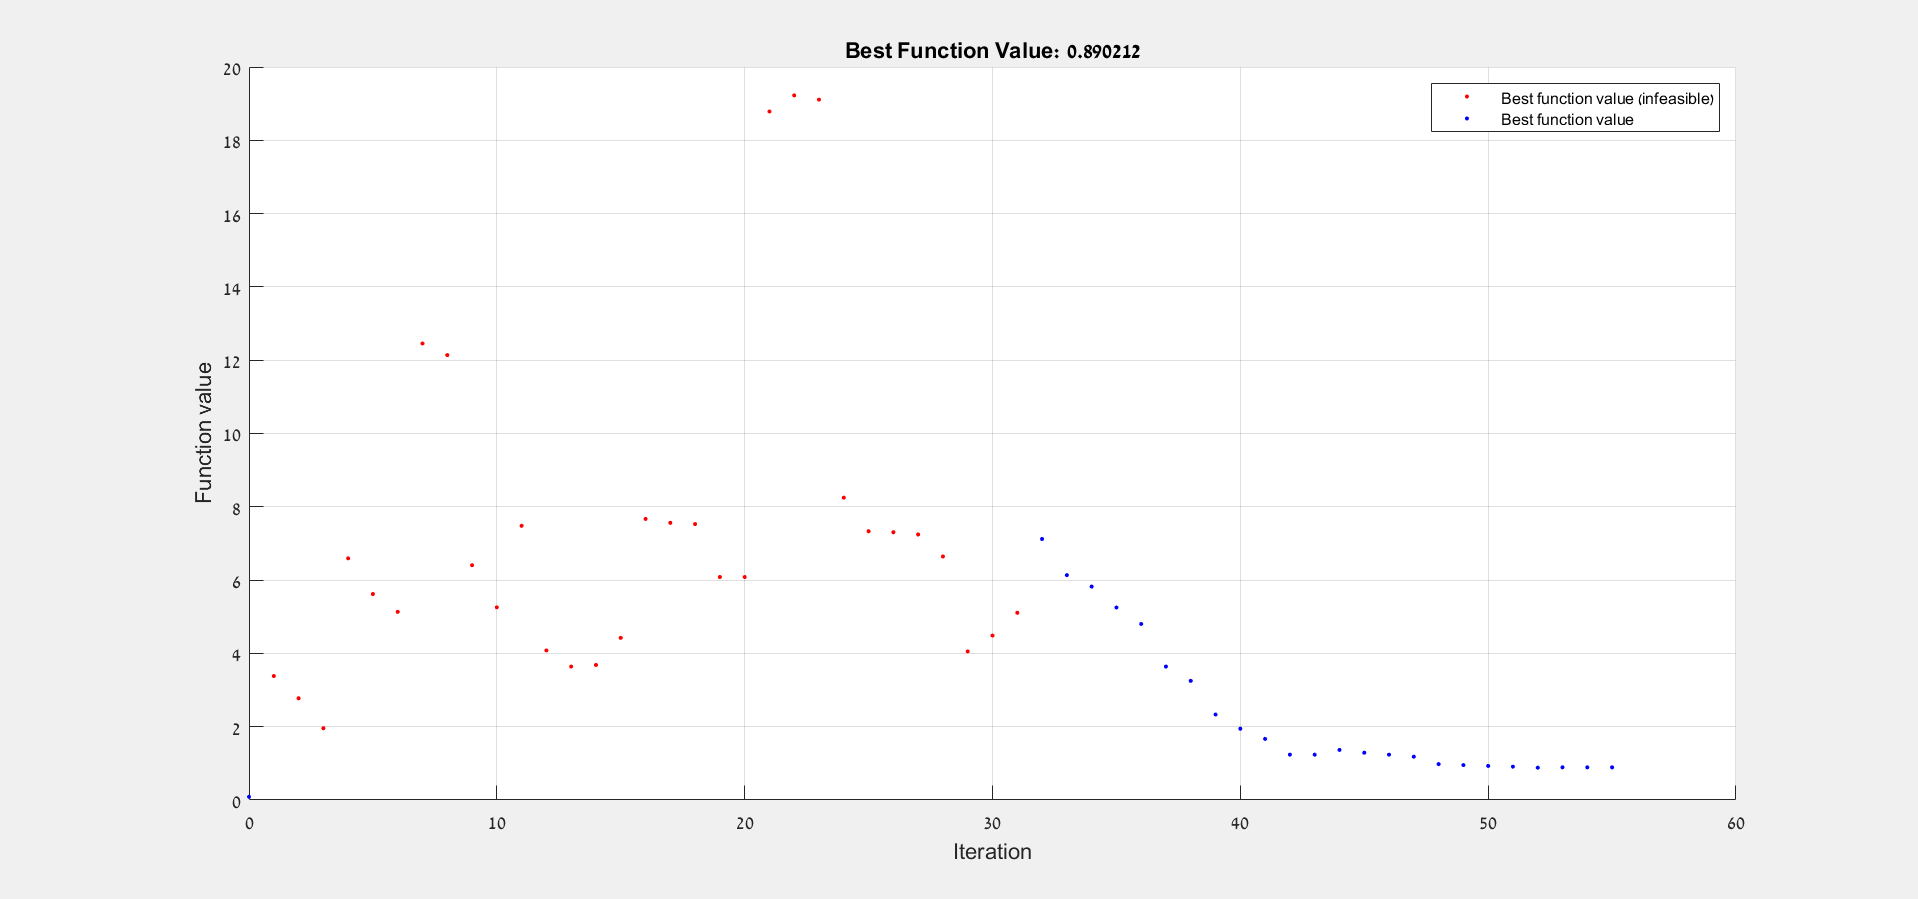


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% Set nondefault solver options
options = optimoptions('fmincon','Display','iter','PlotFcn',...
    'optimplotfvalconstr');

% Solve
[solution,objectiveValue] = fmincon(@objectiveFcn,x0,[],[],[],[],[],[],...
    @constraintFcn,options);


% Clear variables
clearvars options

## optimization function

function f = objectiveFcn(optimInput)

load('var.mat');
% Edit the lines below with your calculation
D2 = optimInput(1);
D3 = optimInput(2);
D4 = optimInput(3);
H2 = optimInput(4);
H3 = optimInput(5);
H4 = optimInput(6);

Is2 = double(subs(Is, [d h],[[0 D2 D3 D4] [0 H2 H3 H4]]));
Fields = FindElectricFiield(Lambda,k,eta,theta_in,Ein,[0 D2 D3 D4],[0 H2 H3 H4],Is2,reff,N);
Impadences= Fields'./Is2;
f= sum(abs(real(Impadences)./imag(Impadences)));
end


## costrains


function [c,ceq] = constraintFcn(optimInput)
load('var.mat');
% Example:
% Constrain a solution to the region
% h2 <= h3
% h3 <= h4
% y = x^3

% Edit the lines below with your calculation
% Note, if no inequality constraints, specify c = []
% Note, if no equality constraints, specify ceq = []
D2 = optimInput(1);
D3 = optimInput(2);
D4 = optimInput(3);
H2 = optimInput(4);
H3 = optimInput(5);
H4 = optimInput(6);

c(1) = H2 - H3;
c(2) = H3 - H4;
c(3) = - H2;
c(4) = - D2;
c(5) = - D3;
c(6) = - D4;
c(7) = D2 - Lambda;
c(8) = D3 - Lambda;
c(9) = D4 - Lambda; 
c(10) = H4 -lambda;
ceq = [];
end
